clear; clc;

%% === Auto setup project path ===
%% === ELEC5305 Project Path Setup (robust & portable) ===
% This replaces the old mfilename-based path logic.

% Step 1: resolve project structure automatically
try
    % Try to locate helper if exists (recommended to keep in src/utils/)
    if exist('elec5305_get_paths','file')
        paths = elec5305_get_paths();
    else
        % Fallback: find project root manually
        startHere = pwd;
        root = startHere;
        for k = 1:8
            if isfolder(fullfile(root,'src')) && isfolder(fullfile(root,'results'))
                break;
            end
            parent = fileparts(root);
            if strcmp(parent,root)
                error("Cannot locate project root containing src/ and results/ folders.");
            end
            root = parent;
        end
        % Build standard folder structure
        paths.root     = root;
        paths.src      = fullfile(root,'src');
        paths.results  = fullfile(root,'results');
        paths.audio    = fullfile(paths.results,'audio');
        paths.plots    = fullfile(paths.results,'plots');
        paths.ml       = fullfile(paths.results,'ml');
        paths.modelFile= fullfile(paths.ml,'instrument_classifier.mat');
    end
catch ME
    rethrow(ME)
end

% Step 2: add source code to MATLAB path
addpath(genpath(paths.src));

% Step 3: make sure output folders exist
if ~isfolder(paths.ml), mkdir(paths.ml); end

% Step 4: define outDir & modelFile variables for later use
outDir    = paths.ml;
modelFile = paths.modelFile;

fprintf('[PATH] Project root: %s\n', paths.root);

[PATH] Project root: D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277


fprintf('[PATH] Results dir : %s\n', outDir);

[PATH] Results dir : D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml


fprintf('[PATH] Model file  : %s\n\n', modelFile);

[PATH] Model file  : D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml\instrument_classifier.mat





%% Load feature data


load("results/ml/philharmonia_features.mat");

fprintf("Loaded %d samples, feature dim = %d\n", size(X,1), size(X,2));

Loaded 5643 samples, feature dim = 30


uniqueLabels = unique(Labels);
fprintf("Detected %d instruments:\n", numel(uniqueLabels));

Detected 9 instruments:


disp(uniqueLabels);

    "bassoon"
    "cello"
    "double_bass"
    "flute"
    "guitar"
    "oboe"
    "trombone"
    "tuba"
    "viola"



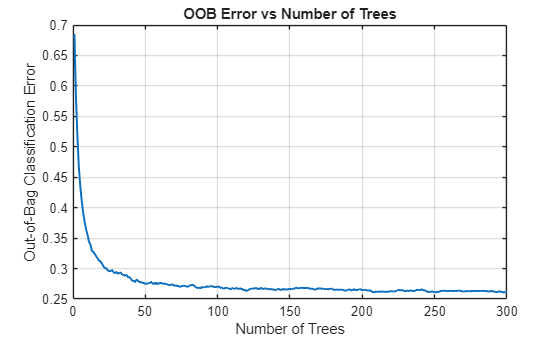


rng(42);                               
Y = categorical(Labels);               
cv = cvpartition(Y,'Holdout',0.2);    

Xtrain = X(training(cv),:);
Ytrain = Y(training(cv));
Xtest  = X(test(cv),:);
Ytest  = Y(test(cv));

mu = mean(Xtrain,1);
sigma = std(Xtrain,[],1);
Xtrain = (Xtrain - mu) ./ (sigma + 1e-6);
Xtest  = (Xtest  - mu) ./ (sigma + 1e-6);

% ============ 2)  ============
MdlRF = TreeBagger(300, Xtrain, Ytrain, ...
    'Method','classification', ...
    'OOBPrediction','On', ...
    'OOBPredictorImportance','On', ...
    'MinLeafSize',5, ...
    'NumPredictorsToSample','all', ...
    'SampleWithReplacement','on');

figure; plot(oobError(MdlRF),'LineWidth',1.5); grid on;
xlabel('Number of Trees'); ylabel('Out-of-Bag Classification Error');
title('OOB Error vs Number of Trees');

exportgraphics(gcf, fullfile(outDir,'oob_error_rf.png'), 'Resolution',220);

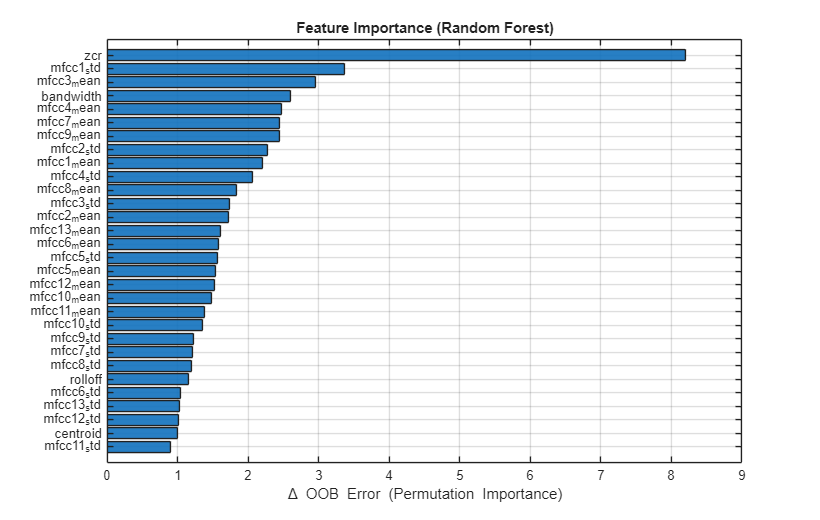




%% === Feature Importance (Random Forest) ===

% 1)
try
    imp = MdlRF.OOBPermutedPredictorDeltaError(:);
catch
    warning('Using oobPermutedPredictorImportance fallback.');
    imp = oobPermutedPredictorImportance(MdlRF);
    imp = imp(:);
end

% 2) 
p = numel(imp);
if exist('Xtrain','var')
    p = size(Xtrain,2); 
end

if p < 4
    error('Feature dimension(%d) is smaller than 4; check your feature vector.', p);
end

remain = p - 4;
if mod(remain,2) ~= 0
    warning('Feature length(%d) not matching 4 + 2*N; naming MFCC generically.', p);
end
n_mfcc = max(1, floor(remain/2));

featNames = strings(1,p);
featNames(1:4) = ["centroid","bandwidth","rolloff","zcr"];
for k = 1:n_mfcc
    idx = 4 + k;
    featNames(idx) = "mfcc" + k + "_mean";
end
for k = 1:n_mfcc
    idx = 4 + n_mfcc + k;
    if idx <= p
        featNames(idx) = "mfcc" + k + "_std";
    end
end
%
emptyIdx = find(featNames=="");
for k = 1:numel(emptyIdx)
    featNames(emptyIdx(k)) = "feat_" + emptyIdx(k);
end

% 3)
[impSorted, idx] = sort(imp, 'descend');
figure('Name','Feature Importance (Random Forest)','Position',[100 100 820 520]);
barh(impSorted, 'FaceAlpha',0.9);
set(gca,'YDir','reverse','FontSize',10);
yticks(1:p);
yticklabels(featNames(idx));
xlabel('\Delta OOB Error (Permutation Importance)');
title('Feature Importance (Random Forest)');
grid on;


% 4) 
K = min(12, p);
T_top = table(featNames(idx(1:K)).', impSorted(1:K), ...
              'VariableNames',{'Feature','DeltaOOBError'});
disp('Top-K important features (Random Forest):');

Top-K important features (Random Forest):


disp(T_top);

      Feature       DeltaOOBError
    ____________    _____________

    "zcr"               8.199    
    "mfcc1_std"        3.3703    
    "mfcc3_mean"       2.9601    
    "bandwidth"        2.6003    
    "mfcc4_mean"       2.4678    
    "mfcc7_mean"       2.4478    
    "mfcc9_mean"       2.4451    
    "mfcc2_std"        2.2787    
    "mfcc1_mean"        2.207    
    "mfcc4_std"        2.0689    
    "mfcc8_mean"       1.8305    
    "mfcc3_std"        1.7359    




% 5) (MFCC mean vs MFCC std）
grp_basic = ismember(featNames, ["centroid","bandwidth","rolloff","zcr"]);
grp_mean  = startsWith(featNames, "mfcc") & endsWith(featNames, "_mean");
grp_std   = startsWith(featNames, "mfcc") & endsWith(featNames, "_std");

sum_basic = sum(imp(grp_basic));
sum_mean  = sum(imp(grp_mean));
sum_std   = sum(imp(grp_std));

T_group = table( ["spectral_basic";"mfcc_mean";"mfcc_std"], ...
                 [sum_basic; sum_mean; sum_std], ...
                 'VariableNames',{'Group','TotalImportance'});
disp('Grouped importance summary:');

Grouped importance summary:


disp(T_group);

         Group          TotalImportance
    ________________    _______________

    "spectral_basic"        12.955     
    "mfcc_mean"             25.181     
    "mfcc_std"                  20     



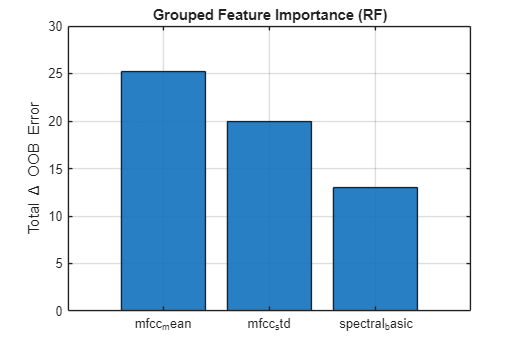


figure('Name','Grouped Importance','Position',[100 100 520 350]);
bar(categorical(T_group.Group), T_group.TotalImportance, 'FaceAlpha',0.9);
ylabel('Total \Delta OOB Error');
title('Grouped Feature Importance (RF)');
grid on;







% ============ 3) SVM ============
tpl = templateSVM('KernelFunction','rbf','KernelScale','auto','BoxConstraint',8);
MdlSVM = fitcecoc(Xtrain, Ytrain, 'Coding','onevsone', 'Learners', tpl);

% ============ 3b) Add two more baseline models ============
MdlKNN = fitcknn(Xtrain, Ytrain, 'NumNeighbors', 5, 'Distance','cosine');     % kNN
MdlNB  = fitcnb( Xtrain, Ytrain, 'DistributionNames','kernel');               % 


% ============ 4) Four models are compared uniformly, and the best one is automatically selected ============

ord = categories(Y);

% 
predict_cat = @(mdl,X) local_predict_cat(mdl, X, ord);

% 
Yhat_RF  = predict_cat(MdlRF,  Xtest);
Yhat_SVM = predict_cat(MdlSVM, Xtest);
Yhat_KNN = predict_cat(MdlKNN, Xtest);
Yhat_NB  = predict_cat(MdlNB,  Xtest);

% Calculate the accuracy rate
acc_RF  = mean(Yhat_RF  == categorical(Ytest,ord));
acc_SVM = mean(Yhat_SVM == categorical(Ytest,ord));
acc_KNN = mean(Yhat_KNN == categorical(Ytest,ord));
acc_NB  = mean(Yhat_NB  == categorical(Ytest,ord));

fprintf('RF Acc  = %.2f%% | SVM Acc = %.2f%% | kNN Acc = %.2f%% | NB Acc = %.2f%%\n', ...
        acc_RF*100, acc_SVM*100, acc_KNN*100, acc_NB*100);

RF Acc  = 75.98% | SVM Acc = 82.54% | kNN Acc = 75.27% | NB Acc = 55.50%



% Form a list and select the best option
names = ["Random Forest","SVM (RBF)","kNN","Naive Bayes"];
accs  = [acc_RF, acc_SVM, acc_KNN, acc_NB];
yhats = {Yhat_RF,  Yhat_SVM, Yhat_KNN, Yhat_NB};
mdls  = {MdlRF,    MdlSVM,   MdlKNN,   MdlNB};

[bestAcc, idx] = max(accs);
bestName = names(idx);
Ypred    = yhats{idx};
Mdl      = mdls{idx};

fprintf('✅ Using model: %s | Test Acc = %.2f%%\n', bestName, bestAcc*100);

✅ Using model: SVM (RBF) | Test Acc = 82.54%







%% =====  =====
classOrder = categories(Y);

%% ===== Batch export of evaluation results: confusion matrix graph, P/R/F1 for each category, summary CSV =====
models   = {'RandomForest','SVM_RBF','kNN_5','NaiveBayes'};
predList = {Yhat_RF,       Yhat_SVM,  Yhat_KNN, Yhat_NB };

Summary = [];
for i = 1:numel(models)
    [acc_i, macroF1_i, C_i, T_i] = local_eval_metrics(Ytest, predList{i}, classOrder);

    f = figure('Name',['Confusion - ' models{i}],'Position',[100 100 780 540]);
    cm = confusionchart(categorical(Ytest,classOrder), categorical(predList{i},classOrder), ...
        'Normalization','row-normalized');
    cm.RowSummary='row-normalized'; cm.ColumnSummary='column-normalized';
    cm.Title = sprintf('Confusion Matrix (%s)', models{i});
    exportgraphics(f, fullfile(outDir, sprintf('confmat_%s.png', models{i})), 'Resolution', 220);
    close(f);

    writetable(T_i, fullfile(outDir, sprintf('perclass_%s.csv', models{i})));

    Summary = [Summary; {models{i}, acc_i, macroF1_i}]; %#ok<AGROW>
end

Tsum = cell2table(Summary, 'VariableNames', {'Model','Accuracy','MacroF1'});
writetable(Tsum, fullfile(outDir,'model_eval_summary.csv'));
disp(Tsum);

         Model          Accuracy    MacroF1
    ________________    ________    _______

    {'RandomForest'}    0.75975     0.75442
    {'SVM_RBF'     }    0.82535     0.81004
    {'kNN_5'       }    0.75266     0.73723
    {'NaiveBayes'  }    0.55496     0.53417



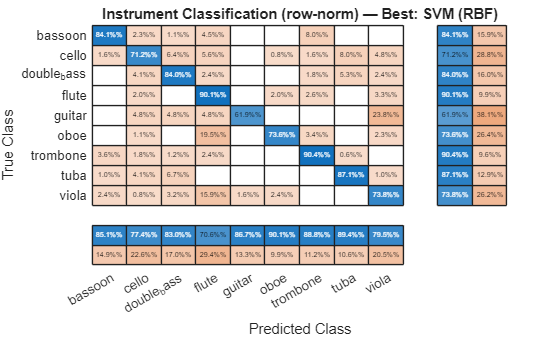


%% ===== Detailed confusion matrix of the sole "best model"=====
[C_best, ~] = confusionmat(categorical(Ytest,classOrder), categorical(Ypred,classOrder));
figure;
cm = confusionchart(categorical(Ytest,classOrder), categorical(Ypred,classOrder), ...
    'Normalization','row-normalized');
cm.CellLabelFormat = '%.1f%%';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.Title = sprintf("Instrument Classification (row-norm) — Best: %s", bestName);
exportgraphics(gcf, fullfile(outDir, sprintf('confmat_best_%s.png', regexprep(bestName,'\W','_'))), 'Resolution', 220);

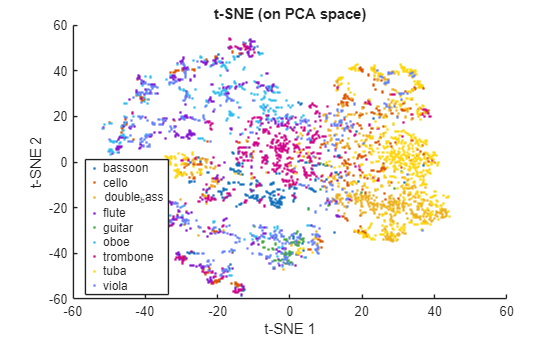


%% ===== t-SNE =====
[coeff,score,~,~,expl] = pca(Xtrain);
k = find(cumsum(expl) > 95, 1);         
Z = tsne(score(:,1:k), 'Perplexity', 30, 'Standardize', true);
figure; gscatter(Z(:,1), Z(:,2), Ytrain);
title('t-SNE (on PCA space)'); xlabel('t-SNE 1'); ylabel('t-SNE 2');
exportgraphics(gcf, fullfile(outDir,'tsne_pca95.png'), 'Resolution', 220);


%% ============ Open-set stats for "Unknown" ============ 

Xtr_std = Xtrain;             
Ytr_cat = categorical(Ytrain);
classes = categories(Ytr_cat);
p = size(Xtr_std,2);
C = numel(classes);

classStats = struct();
classStats.classes  = classes;
classStats.mu       = zeros(C,p);
classStats.Sigma    = zeros(p,p,C);
classStats.invSigma = zeros(p,p,C);
classStats.tau_maha = zeros(C,1);  
lambda = 1e-3;                     

for c = 1:C
    idx  = (Ytr_cat == classes{c});
    Xc   = Xtr_std(idx,:);
    mu_c = mean(Xc,1);

    Sigma_c = cov(Xc) + lambda*eye(p);
    iSig_c  = pinv(Sigma_c);

    classStats.mu(c,:)        = mu_c;
    classStats.Sigma(:,:,c)   = Sigma_c;
    classStats.invSigma(:,:,c)= iSig_c;


    diffs = Xc - mu_c;
    % d^2 = sum((diffs*iSig).*diffs, 2)
    d2 = sum((diffs * iSig_c) .* diffs, 2);
    d  = sqrt(d2);
    classStats.tau_maha(c) = quantile(d, 0.95);
end


openSet = struct();
openSet.prob_threshold = -0.125; 
openSet.min_vote_share = 0.70;


bestModelName = char(bestName);
[classAcc, classF1, ~, ~] = local_eval_metrics(Ytest, Ypred, classOrder);
metrics = struct('RF',acc_RF,'SVM',acc_SVM,'kNN',acc_KNN,'NB',acc_NB, ...
                 'BestAcc',bestAcc,'BestName',bestModelName,'MacroF1',classF1);

uniqueLabels = categories(Y);
modelFile = fullfile(outDir,'instrument_classifier.mat');  % 与预测脚本一致
save(modelFile, "Mdl","mu","sigma","uniqueLabels","bestModelName","metrics", ...
                 "classStats","openSet");
fprintf("✅ Model+OpenSet saved -> %s\n", modelFile);

✅ Model+OpenSet saved -> D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml\instrument_classifier.mat




whos('-file', modelFile);

  Name               Size              Bytes  Class                 Attributes

  Mdl                1x1             4199095  ClassificationECOC              
  bestModelName      1x9                  18  char                            
  classStats         1x1              133708  struct                          
  metrics            1x1                1010  struct                          
  mu                 1x30                240  double                          
  openSet            1x1                 316  struct                          
  sigma              1x30                240  double                          
  uniqueLabels       9x1                1190  cell                            





%% ======== The local functions used in this script========
function [acc, macroF1, C, tbl] = local_eval_metrics(Ytrue, Ypred, classes)

Ytrue = categorical(Ytrue, classes);
Ypred = categorical(Ypred, classes);
C = confusionmat(Ytrue, Ypred, 'Order', classes);

prec = diag(C) ./ max(1, sum(C,1))'; 
rec  = diag(C) ./ max(1, sum(C,2)); 
f1   = 2*prec.*rec ./ max(1e-12,prec+rec);

acc = mean(Ytrue == Ypred);
macroF1 = mean(f1);

tbl = table(classes, prec, rec, f1, ...
    'VariableNames',{'Class','Precision','Recall','F1'});
end

function ycat = local_predict_cat(mdl, X, ord)

    y = predict(mdl, X);
    ycat = local_toCat(y, ord);
end

function ycat = local_toCat(y, ord)

    if iscategorical(y)
        ycat = categorical(y, ord);
    elseif iscell(y)
        ycat = categorical(string(y), ord);
    elseif isstring(y)
        ycat = categorical(y, ord);
    elseif ischar(y)
        ycat = categorical(string(y), ord);
    else
        ycat = categorical(string(y), ord); 
    end
end


% ====== Auxiliary function: Search for the root upwards ======
function root = find_project_root(startPath)
    root = startPath;
    for i = 1:10
        hasGit  = isfolder(fullfile(root,'.git'));
        hasSrc  = isfolder(fullfile(root,'src'));
        hasRes  = isfolder(fullfile(root,'results'));
        if hasGit || (hasSrc && hasRes)
            return;
        end
        parent = fileparts(root);
        if strcmp(parent,root), return; end
        root = parent;
    end
end